imagesFolder = fullfile(toolboxdir("nnet"),"nndemos","nndatasets","DigitDataset");

imds = imageDatastore(imagesFolder,"IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn:

idx = 1471;
[img, imgInfo] = readimage(imds,idx);
imgInfo

imgInfo = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\1\image521.png'
    FileSize: 235
       Label: 1


imgBW = imbinarize(img);
props = regionprops("table",imgBW,"Orientation")

props = table
    Orientation
    ___________

      78.187   


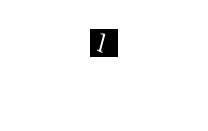

imshow(img)

imagesFolder = fullfile(toolboxdir("nnet"),"nndemos","nndatasets","DigitDataset");

imds = imageDatastore(imagesFolder,"IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn:


Image = [];
Label = [];
Angle = [];

while hasdata(imds)
    [img, imgInfo] = read(imds);
    imgBW = imbinarize(img);              
    props = regionprops("table",imgBW,"Orientation");
    
    if height(props) == 1
        Image = [Image;string(imgInfo.Filename)];
        Label = [Label; imgInfo.Label];
        Angle = [Angle; props.Orientation];
    end
end

digitData = table(Image,Label,Angle)

digitData = 8954×3 table
                                                Image                                                 Label     Angle 
    ______________________________________________________________________________________________    _____    _______

    "C:\Program Files\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png"      0       6.7263
    "C:\Program Files\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png"       0       82.052
    "C:\Program Files\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png"       0      -44.263
    "C:\Program Files\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9003.png"       0       78.965
    "C:\Program Files\MATLAB\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9004.png"       0       70.774
    "C:\Program Files\MATLAB\R2023a\too

puzzleFolder = fullfile("Image Processing for Engineering and Science/Data/MathWorks Images/MathWorks Puzzle")

puzzleFolder = "Image Processing for Engineering and Science\Data\MathWorks Images\MathWorks Puzzle"

imds = imageDatastore(puzzleFolder);
sumoo=0;
k=0;
areasum = 0;
while hasdata(imds)
    [img, imgInfo] = read(imds);
    [bw,props]=processPuzzle(img);   
    [~, numRegions] = bwlabel(bw);
    sumoo = sumoo + numRegions;
    properties2 = regionprops("table",bw,"Area"); 
    totalArea = sum(properties2.Area);
    areasum = areasum + totalArea;
end

areasum

areasum = 9893659

sumoo

sumoo = 628

puzzle1 = imread("Puzzle_01.jpg")

puzzle1 = 1512×1512×3 uint8 array
puzzle1(:,:,1) =

   117   128   116   121   126   120   125   122   112   114   109   115   115   108   111   104   117   116   115   113   113   120   124   121   109   118   120   125   114   111   104    98   116   122   123   139   128   103   108   106   113   102   103   116   131   123   100    99   104   116   108   101   115   139   129   131   140   143   142   133   100   105   112   111   107   108   122   128   124   129   128   113    95    92   110   131   131   130   132   120   104   103   128   122    92    93   115   138   137   135   127   121   131   132   113   105    90    94   117   127   117   105   104   119   116   123   122   119   111   121   117   113   122   123   107   117   117    96   111   134   134   117   103   115   132   129   122   123   107   108   106   114   115   129   131   137   121   135   139   135   137   147   142   126   129   124   124   140   138   126   131   129   140   145   128   109   113   121

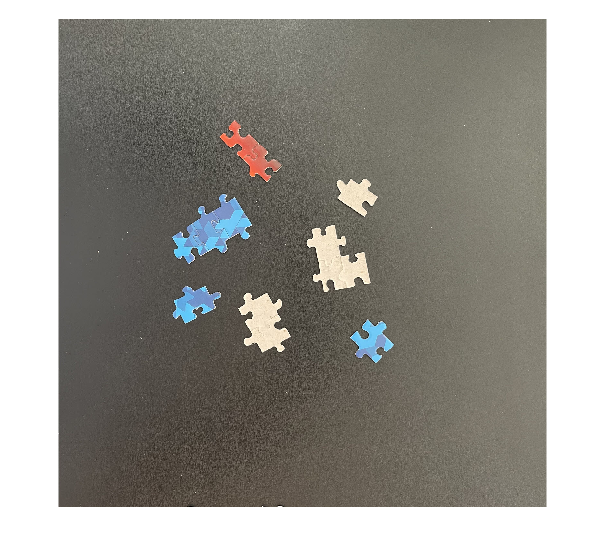

imshow(puzzle1)

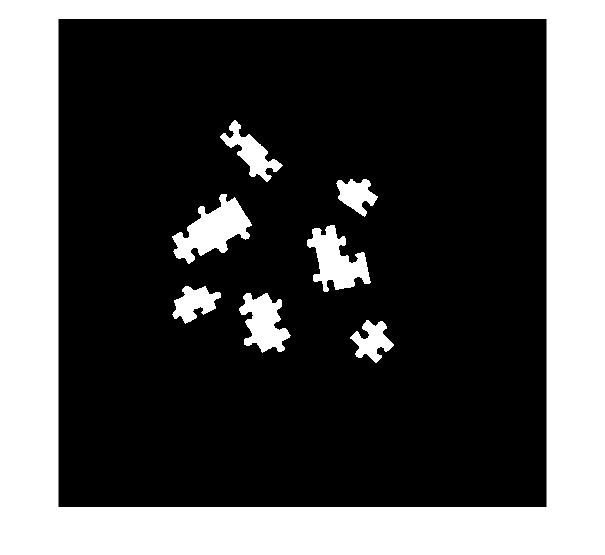

[bw,props]=processPuzzle(puzzle1);
imshow(bw)

nnz(bw)

ans = 104697

properties2 = regionprops("table",bw,"Area") 

properties2 = 7×1 table
    Area 
    _____

    25654
     9841
    12390
    17529
    21455
     8559
     9269


totalArea = sum(properties2.Area);
totalArea

totalArea = 104697

[~, numRegions] = bwlabel(bw);
numRegions

numRegions = 7

puzzle13 = imread("Puzzle_13.jpg")

puzzle13 = 1512×1512×3 uint8 array
puzzle13(:,:,1) =

   124   101   132   107   138   108    53    97   107    84   112   128   117   102    65    88    59    83    98    67    83   121   103    92   150   170   113    92    84   126   145   105    79    58    65   105   142   122    96   112   120   124    82    58    81    93    85   105    95    91    75    80    56   108    78    72   118   102   109   122   163   113   101   124   121   109   117   128   129    96    86   112   138   102    93   173   124    74   140   112    85    80   112   144   102   145   171   119   133   130   105    94   101    93    98    89    84    86    69   112   164   147    99    72    83   162   144   133   160   113    66    55    76   113   103   126   127    79    97   103   109   182   139   102   113    75    97   118    84   118   141   123    83    56    74   122   131   109    55   109   156   154   127   138   111    61    83   129   154   145   112    86    77    70    70    90    67    

puzzle27 = imread("Puzzle_27.jpg")

puzzle27 = 1512×1512×3 uint8 array
puzzle27(:,:,1) =

   119   126   134   141   130   118   127   134   113   127   130   115   123   127   113   127   141   134   144   138   133   138   130   129   125   110   118   121   111   120   131   122   138   136   116   122   142   163   122   121   138   129   117   124   126   120   123   121   125   135   117   111   130   114   100   130   130   120   130   132   126   139   140   116   102   106   114   123   118   122   135   124   114   133   149   141   103   119   123   134   131   116   130   118   114   117   119   128   130   137   131   143   138   137   128   117   116   127   126   141   126   120   127   123   111   128   142   119   115   139   151   109    93   131   140   148   112    99   103   122   139   118   109   141   142   131   150   144   124   130   133   139   128   124   142   112   106   152   154   159   161   138   116   129   127   118   115   109   105   108   139   113   139   121   121   132   108    

puzzle42 = imread("Puzzle_42.jpg")

puzzle42 = 1512×1512×3 uint8 array
puzzle42(:,:,1) =

   134   134   135   135   133   131   129   128   132   132   132   132   133   133   133   133   134   134   133   133   133   133   132   132   129   133   134   132   133   137   137   135   134   134   132   132   132   133   135   136   133   133   133   133   132   132   132   132   131   131   131   132   133   133   134   134   133   133   132   132   133   135   137   138   137   137   137   137   137   137   137   137   134   134   134   134   135   135   135   135   134   134   134   134   134   134   134   134   132   133   133   134   134   135   135   136   134   131   131   134   134   131   131   134   132   133   135   136   136   136   135   135   136   136   136   136   136   136   136   136   132   134   136   137   137   136   134   132   131   133   136   138   137   134   130   128   134   137   133   132   137   136   135   140   134   134   134   133   133   133   132   132   132   133   135   136   137   1

puzzle49 = imread("Puzzle_49.jpg")

puzzle49 = 1512×1512×3 uint8 array
puzzle49(:,:,1) =

   105    93   119   142   122   105   111   113   115   103   103   117   106    97   116   119    85    86    87    89   113   118   109   103   101   103    91   107   113    96   102   116   122   103    96   103   107    89    71    89    98   111   113    95    85    91    94    95   129   138   124   115   117   111    84    85    91   106   115   119   115    88    79   112   137   147    95    93    94    86   101   111   100    84    97   124   108    74    89   133   138   119    99    89    95   113   118   106    93   101    97    96   110   142   122    90   129   156   112    86   115   105   121   121   133   111   100    97   140   157   139   121   119   116   116   111    95    94    97   114   113   110   126   107   131    99   108   143   103    86    96   145   140    95    78    88   109    84   102   143   114    85   125   136    87   102   118    74   100   102    94    89    98   152   132   104   108   1


bw13=processPuzzle(puzzle13)

bw13 = 1512×1512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

bw27=processPuzzle(puzzle27)

bw27 = 1512×1512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

bw42=processPuzzle(puzzle42)

bw42 = 1512×1512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

bw49=processPuzzle(puzzle49)

bw49 = 1512×1512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

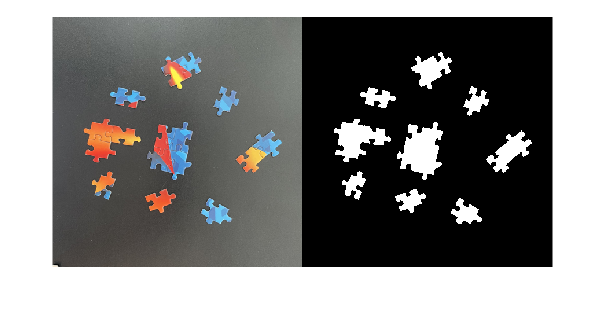

montage({puzzle13,bw13})

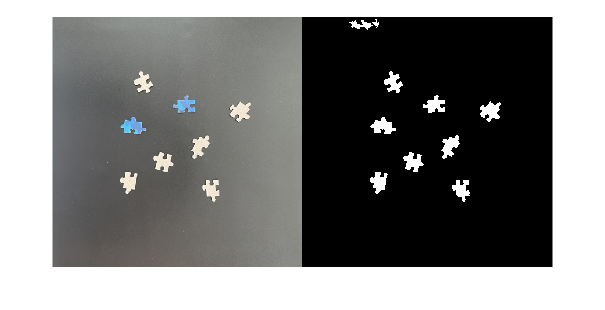

montage({puzzle27,bw27})

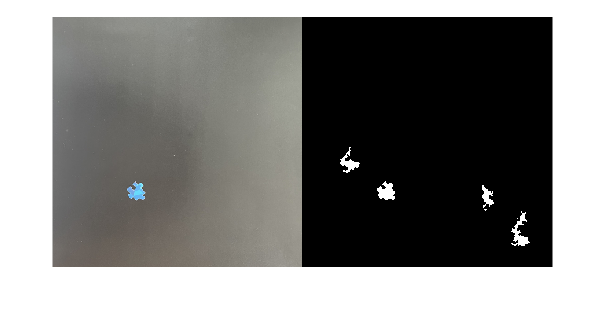

montage({puzzle42,bw42})

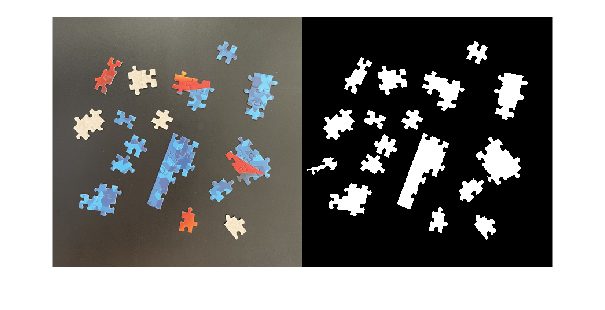

montage({puzzle49,bw49})

v = VideoReader("liquidVideo.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'liquidVideo.mp4'
            Path: 'C:\Users\backupadmin\Documents\ImageProcessingCoursera\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 120
          Height: 216
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


v.FrameRate

ans = 10

vOut = VideoWriter("LiquidVideoBinary.mp4","MPEG-4")

vOut =   VideoWriter

    General Properties:

       Filename:                 'LiquidVideoBinary.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


vOut.FrameRate = v.FrameRate

vOut =   VideoWriter

    General Properties:

       Filename:                 'LiquidVideoBinary.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


n = v.NumFrames;

open(vOut)

for i=1:n
    img =readFrame(v);
    bw=liquidMask(img);

    frame = imfuse(img,bw,"montage");
    writeVideo(vOut,frame)

    liquidPart = nnz(bw)
    emptyPart = nnz(~bw)

    time=v.CurrentTime
end

liquidPart = 0

emptyPart = 25920

time = 0.2000

liquidPart = 0

emptyPart = 25920

time = 0.3000

liquidPart = 0

emptyPart = 25920

time = 0.4000

liquidPart = 0

emptyPart = 25920

time = 0.5000

liquidPart = 0

emptyPart = 25920

time = 0.6000

liquidPart = 0

emptyPart = 25920

time = 0.7000

liquidPart = 0

emptyPart = 25920

time = 0.8000

liquidPart = 0

emptyPart = 25920

time = 0.9000

liquidPart = 0

emptyPart = 25920

time = 1

liquidPart = 0

emptyPart = 25920

time = 1.1000

liquidPart = 0

emptyPart = 25920

time = 1.2000

liquidPart = 0

emptyPart = 25920

time = 1.3000

liquidPart = 0

emptyPart = 25920

time = 1.4000

liquidPart = 0

emptyPart = 25920

time = 1.5000

liquidPart = 0

emptyPart = 25920

time = 1.6000

liquidPart = 0

emptyPart = 25920

time = 1.7000

liquidPart = 0

emptyPart = 25920

time = 1.8000

liquidPart = 0

emptyPart = 25920

time = 1.9000

liquidPart = 0

emptyPart = 25920

time = 2

liquidPart = 0

emptyPart = 25920

time = 2.1000

liquidPart = 1

emptyPart = 25919

time = 2.2000

liquidPart = 0

emptyPart = 25920

time = 2.3000

liquidPart = 0

emptyPart = 25920

time = 2.4000

liquidPart = 0

emptyPart = 25920

time = 2.5000

liquidPart = 0

emptyPart = 25920

time = 2.6000

liquidPart = 0

emptyPart = 25920

time = 2.7000

liquidPart = 0

emptyPart = 25920

time = 2.8000

liquidPart = 0

emptyPart = 25920

time = 2.9000

liquidPart = 0

emptyPart = 25920

time = 3

liquidPart = 0

emptyPart = 25920

time = 3.1000

liquidPart = 1

emptyPart = 25919

time = 3.2000

liquidPart = 1

emptyPart = 25919

time = 3.3000

liquidPart = 1

emptyPart = 25919

time = 3.4000

liquidPart = 0

emptyPart = 25920

time = 3.5000

liquidPart = 0

emptyPart = 25920

time = 3.6000

liquidPart = 0

emptyPart = 25920

time = 3.7000

liquidPart = 1

emptyPart = 25919

time = 3.8000

liquidPart = 1

emptyPart = 25919

time = 3.9000

liquidPart = 0

emptyPart = 25920

time = 4

liquidPart = 0

emptyPart = 25920

time = 4.1000

liquidPart = 0

emptyPart = 25920

time = 4.2000

liquidPart = 0

emptyPart = 25920

time = 4.3000

liquidPart = 0

emptyPart = 25920

time = 4.4000

liquidPart = 0

emptyPart = 25920

time = 4.5000

liquidPart = 0

emptyPart = 25920

time = 4.6000

liquidPart = 10

emptyPart = 25910

time = 4.7000

liquidPart = 17

emptyPart = 25903

time = 4.8000

liquidPart = 52

emptyPart = 25868

time = 4.9000

liquidPart = 284

emptyPart = 25636

time = 5

liquidPart = 274

emptyPart = 25646

time = 5.1000

liquidPart = 461

emptyPart = 25459

time = 5.2000

liquidPart = 558

emptyPart = 25362

time = 5.3000

liquidPart = 651

emptyPart = 25269

time = 5.4000

liquidPart = 1005

emptyPart = 24915

time = 5.5000

liquidPart = 1057

emptyPart = 24863

time = 5.6000

liquidPart = 1087

emptyPart = 24833

time = 5.7000

liquidPart = 1431

emptyPart = 24489

time = 5.8000

liquidPart = 1576

emptyPart = 24344

time = 5.9000

liquidPart = 1554

emptyPart = 24366

time = 6

liquidPart = 1745

emptyPart = 24175

time = 6.1000

liquidPart = 2019

emptyPart = 23901

time = 6.2000

liquidPart = 2001

emptyPart = 23919

time = 6.3000

liquidPart = 2085

emptyPart = 23835

time = 6.4000

liquidPart = 2338

emptyPart = 23582

time = 6.5000

liquidPart = 2479

emptyPart = 23441

time = 6.6000

liquidPart = 2712

emptyPart = 23208

time = 6.7000

liquidPart = 2796

emptyPart = 23124

time = 6.8000

liquidPart = 2916

emptyPart = 23004

time = 6.9000

liquidPart = 3222

emptyPart = 22698

time = 7

liquidPart = 3347

emptyPart = 22573

time = 7.1000

liquidPart = 3346

emptyPart = 22574

time = 7.2000

liquidPart = 3639

emptyPart = 22281

time = 7.3000

liquidPart = 4026

emptyPart = 21894

time = 7.4000

liquidPart = 4070

emptyPart = 21850

time = 7.5000

liquidPart = 4177

emptyPart = 21743

time = 7.6000

liquidPart = 4520

emptyPart = 21400

time = 7.7000

liquidPart = 4766

emptyPart = 21154

time = 7.8000

liquidPart = 4927

emptyPart = 20993

time = 7.9000

liquidPart = 5164

emptyPart = 20756

time = 8

liquidPart = 5426

emptyPart = 20494

time = 8.1000

liquidPart = 5415

emptyPart = 20505

time = 8.2000

liquidPart = 5663

emptyPart = 20257

time = 8.3000

liquidPart = 5880

emptyPart = 20040

time = 8.4000

liquidPart = 5978

emptyPart = 19942

time = 8.5000

liquidPart = 6184

emptyPart = 19736

time = 8.6000

liquidPart = 6190

emptyPart = 19730

time = 8.7000

liquidPart = 6229

emptyPart = 19691

time = 8.8000

liquidPart = 6343

emptyPart = 19577

time = 8.9000

liquidPart = 6297

emptyPart = 19623

time = 9

liquidPart = 6285

emptyPart = 19635

time = 9.1000

liquidPart = 6464

emptyPart = 19456

time = 9.2000

liquidPart = 6520

emptyPart = 19400

time = 9.3000

liquidPart = 6494

emptyPart = 19426

time = 9.4000

liquidPart = 6612

emptyPart = 19308

time = 9.5000

liquidPart = 6627

emptyPart = 19293

time = 9.6000

liquidPart = 6693

emptyPart = 19227

time = 9.7000

liquidPart = 6794

emptyPart = 19126

time = 9.8000

liquidPart = 6804

emptyPart = 19116

time = 9.9000

liquidPart = 6897

emptyPart = 19023

time = 10

liquidPart = 6923

emptyPart = 18997

time = 10.1000

liquidPart = 6998

emptyPart = 18922

time = 10.2000

liquidPart = 7107

emptyPart = 18813

time = 10.3000

liquidPart = 7129

emptyPart = 18791

time = 10.4000

liquidPart = 7117

emptyPart = 18803

time = 10.5000

liquidPart = 7151

emptyPart = 18769

time = 10.6000

liquidPart = 7318

emptyPart = 18602

time = 10.7000

liquidPart = 7376

emptyPart = 18544

time = 10.8000

liquidPart = 7476

emptyPart = 18444

time = 10.9000

liquidPart = 7478

emptyPart = 18442

time = 11

liquidPart = 7508

emptyPart = 18412

time = 11.1000

liquidPart = 7670

emptyPart = 18250

time = 11.2000

liquidPart = 7764

emptyPart = 18156

time = 11.3000

liquidPart = 7783

emptyPart = 18137

time = 11.4000

liquidPart = 8073

emptyPart = 17847

time = 11.5000

liquidPart = 7982

emptyPart = 17938

time = 11.6000

liquidPart = 7975

emptyPart = 17945

time = 11.7000

liquidPart = 8164

emptyPart = 17756

time = 11.8000

liquidPart = 8343

emptyPart = 17577

time = 11.9000

liquidPart = 8344

emptyPart = 17576

time = 12

liquidPart = 8405

emptyPart = 17515

time = 12.1000

liquidPart = 8416

emptyPart = 17504

time = 12.2000

liquidPart = 8395

emptyPart = 17525

time = 12.3000

liquidPart = 8612

emptyPart = 17308

time = 12.4000

liquidPart = 8655

emptyPart = 17265

time = 12.5000

liquidPart = 8817

emptyPart = 17103

time = 12.6000

liquidPart = 8806

emptyPart = 17114

time = 12.7000

liquidPart = 8820

emptyPart = 17100

time = 12.8000

liquidPart = 8831

emptyPart = 17089

time = 12.9000

liquidPart = 8942

emptyPart = 16978

time = 13

liquidPart = 9024

emptyPart = 16896

time = 13.1000

liquidPart = 9076

emptyPart = 16844

time = 13.2000

liquidPart = 9159

emptyPart = 16761

time = 13.3000

liquidPart = 9185

emptyPart = 16735

time = 13.4000

liquidPart = 9145

emptyPart = 16775

time = 13.5000

liquidPart = 9366

emptyPart = 16554

time = 13.6000

liquidPart = 9412

emptyPart = 16508

time = 13.7000

liquidPart = 9433

emptyPart = 16487

time = 13.8000

liquidPart = 9528

emptyPart = 16392

time = 13.9000

liquidPart = 9582

emptyPart = 16338

time = 14

liquidPart = 9714

emptyPart = 16206

time = 14.1000

liquidPart = 9906

emptyPart = 16014

time = 14.2000

liquidPart = 10057

emptyPart = 15863

time = 14.3000

liquidPart = 10151

emptyPart = 15769

time = 14.4000

liquidPart = 10282

emptyPart = 15638

time = 14.5000

liquidPart = 10374

emptyPart = 15546

time = 14.6000

liquidPart = 10440

emptyPart = 15480

time = 14.7000

liquidPart = 10698

emptyPart = 15222

time = 14.8000

liquidPart = 10840

emptyPart = 15080

time = 14.9000

liquidPart = 10959

emptyPart = 14961

time = 15

liquidPart = 11111

emptyPart = 14809

time = 15.1000

liquidPart = 11189

emptyPart = 14731

time = 15.2000

liquidPart = 11292

emptyPart = 14628

time = 15.3000

liquidPart = 11526

emptyPart = 14394

time = 15.4000

liquidPart = 11756

emptyPart = 14164

time = 15.5000

liquidPart = 11866

emptyPart = 14054

time = 15.6000

liquidPart = 12133

emptyPart = 13787

time = 15.7000

liquidPart = 12261

emptyPart = 13659

time = 15.8000

liquidPart = 12497

emptyPart = 13423

time = 15.9000

liquidPart = 12697

emptyPart = 13223

time = 16

liquidPart = 12956

emptyPart = 12964

time = 16.1000

liquidPart = 13402

emptyPart = 12518

time = 16.2000

liquidPart = 13337

emptyPart = 12583

time = 16.3000

liquidPart = 13648

emptyPart = 12272

time = 16.4000

liquidPart = 14003

emptyPart = 11917

time = 16.5000

liquidPart = 14124

emptyPart = 11796

time = 16.6000

liquidPart = 14261

emptyPart = 11659

time = 16.7000

liquidPart = 14513

emptyPart = 11407

time = 16.8000

liquidPart = 14812

emptyPart = 11108

time = 16.9000

liquidPart = 14938

emptyPart = 10982

time = 17

liquidPart = 15049

emptyPart = 10871

time = 17.1000

liquidPart = 15407

emptyPart = 10513

time = 17.2000

liquidPart = 15622

emptyPart = 10298

time = 17.3000

liquidPart = 15766

emptyPart = 10154

time = 17.4000

liquidPart = 15994

emptyPart = 9926

time = 17.5000

liquidPart = 15871

emptyPart = 10049

time = 17.6000

liquidPart = 16222

emptyPart = 9698

time = 17.7000

liquidPart = 16449

emptyPart = 9471

time = 17.8000

liquidPart = 16744

emptyPart = 9176

time = 17.9000

liquidPart = 17026

emptyPart = 8894

time = 18

liquidPart = 17400

emptyPart = 8520

time = 18.1000

liquidPart = 17077

emptyPart = 8843

time = 18.2000

liquidPart = 17799

emptyPart = 8121

time = 18.3000

liquidPart = 17933

emptyPart = 7987

time = 18.4000

liquidPart = 17926

emptyPart = 7994

time = 18.5000

liquidPart = 18338

emptyPart = 7582

time = 18.6000

liquidPart = 18710

emptyPart = 7210

time = 18.7000

liquidPart = 18765

emptyPart = 7155

time = 18.8000

liquidPart = 19112

emptyPart = 6808

time = 18.9000

liquidPart = 19431

emptyPart = 6489

time = 19

liquidPart = 19774

emptyPart = 6146

time = 19.1000

liquidPart = 19822

emptyPart = 6098

time = 19.2000

liquidPart = 20265

emptyPart = 5655

time = 19.3000

liquidPart = 20234

emptyPart = 5686

time = 19.4000

liquidPart = 20365

emptyPart = 5555

time = 19.5000

liquidPart = 21167

emptyPart = 4753

time = 19.6000

liquidPart = 20876

emptyPart = 5044

time = 19.7000

liquidPart = 21304

emptyPart = 4616

time = 19.8000

liquidPart = 21558

emptyPart = 4362

time = 19.9000

liquidPart = 21689

emptyPart = 4231

time = 20

liquidPart = 22100

emptyPart = 3820

time = 20.1000

liquidPart = 22076

emptyPart = 3844

time = 20.2000

liquidPart = 21942

emptyPart = 3978

time = 20.3000

liquidPart = 22811

emptyPart = 3109

time = 20.4000

liquidPart = 22570

emptyPart = 3350

time = 20.5000

liquidPart = 22655

emptyPart = 3265

time = 20.6000

liquidPart = 22760

emptyPart = 3160

time = 20.7000

liquidPart = 23206

emptyPart = 2714

time = 20.8000

liquidPart = 23211

emptyPart = 2709

time = 20.9000

liquidPart = 23117

emptyPart = 2803

time = 21

liquidPart = 23172

emptyPart = 2748

time = 21.1000

liquidPart = 23376

emptyPart = 2544

time = 21.2000

liquidPart = 23472

emptyPart = 2448

time = 21.3000

liquidPart = 23471

emptyPart = 2449

time = 21.4000

liquidPart = 23520

emptyPart = 2400

time = 21.5000

liquidPart = 23684

emptyPart = 2236

time = 21.6000

liquidPart = 23696

emptyPart = 2224

time = 21.7000

liquidPart = 23738

emptyPart = 2182

time = 21.8000

liquidPart = 23844

emptyPart = 2076

time = 21.9000

liquidPart = 23916

emptyPart = 2004

time = 22

liquidPart = 23923

emptyPart = 1997

time = 22.1000

liquidPart = 23968

emptyPart = 1952

time = 22.2000

liquidPart = 24120

emptyPart = 1800

time = 22.3000

liquidPart = 24227

emptyPart = 1693

time = 22.4000

liquidPart = 24228

emptyPart = 1692

time = 22.5000

liquidPart = 24266

emptyPart = 1654

time = 22.6000

liquidPart = 24376

emptyPart = 1544

time = 22.7000

liquidPart = 24478

emptyPart = 1442

time = 22.8000

liquidPart = 24572

emptyPart = 1348

time = 22.9000

liquidPart = 24614

emptyPart = 1306

time = 23

liquidPart = 24711

emptyPart = 1209

time = 23.1000

liquidPart = 24734

emptyPart = 1186

time = 23.2000

liquidPart = 24859

emptyPart = 1061

time = 23.3000

liquidPart = 25065

emptyPart = 855

time = 23.4000

liquidPart = 25211

emptyPart = 709

time = 23.5000

liquidPart = 25335

emptyPart = 585

time = 23.6000

liquidPart = 25456

emptyPart = 464

time = 23.7000

liquidPart = 25672

emptyPart = 248

time = 23.8000

liquidPart = 25841

emptyPart = 79

time = 23.9000

liquidPart = 25896

emptyPart = 24

time = 24

liquidPart = 25907

emptyPart = 13

time = 24


close(vOut)

v.CurrentTime = 0;

shuttle = VideoReader("shuttle.avi")

shuttle =   VideoReader with properties:

   General Properties:
            Name: 'shuttle.avi'
            Path: 'C:\Program Files\MATLAB\R2023a\toolbox\matlab\demos'
        Duration: 4.0333
     CurrentTime: 0
       NumFrames: 121

   Video Properties:
           Width: 512
          Height: 288
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


shuttle.FrameRate

ans = 30

vOut = VideoWriter("RocketBinaryFlame.mp4","MPEG-4")

vOut =   VideoWriter

    General Properties:

       Filename:                 'RocketBinaryFlame.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


vOut.FrameRate = shuttle.FrameRate

vOut =   VideoWriter

    General Properties:

       Filename:                 'RocketBinaryFlame.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods



open(vOut)

for i=1:118
    img = readFrame(shuttle);
    bw = FireEscape(img);

    writeVideo(vOut,img)

    liquidPart = nnz(bw)
    emptyPart = nnz(~bw)

    time=v.CurrentTime
end

liquidPart = 419

emptyPart = 147037

time = 24

liquidPart = 434

emptyPart = 147022

time = 24

liquidPart = 422

emptyPart = 147034

time = 24

liquidPart = 409

emptyPart = 147047

time = 24

liquidPart = 433

emptyPart = 147023

time = 24

liquidPart = 449

emptyPart = 147007

time = 24

liquidPart = 463

emptyPart = 146993

time = 24

liquidPart = 481

emptyPart = 146975

time = 24

liquidPart = 472

emptyPart = 146984

time = 24

liquidPart = 480

emptyPart = 146976

time = 24

liquidPart = 497

emptyPart = 146959

time = 24

liquidPart = 503

emptyPart = 146953

time = 24

liquidPart = 538

emptyPart = 146918

time = 24

liquidPart = 543

emptyPart = 146913

time = 24

liquidPart = 560

emptyPart = 146896

time = 24

liquidPart = 596

emptyPart = 146860

time = 24

liquidPart = 611

emptyPart = 146845

time = 24

liquidPart = 637

emptyPart = 146819

time = 24

liquidPart = 664

emptyPart = 146792

time = 24

liquidPart = 663

emptyPart = 146793

time = 24

liquidPart = 714

emptyPart = 146742

time = 24

liquidPart = 733

emptyPart = 146723

time = 24

liquidPart = 742

emptyPart = 146714

time = 24

liquidPart = 803

emptyPart = 146653

time = 24

liquidPart = 845

emptyPart = 146611

time = 24

liquidPart = 840

emptyPart = 146616

time = 24

liquidPart = 864

emptyPart = 146592

time = 24

liquidPart = 865

emptyPart = 146591

time = 24

liquidPart = 887

emptyPart = 146569

time = 24

liquidPart = 888

emptyPart = 146568

time = 24

liquidPart = 884

emptyPart = 146572

time = 24

liquidPart = 906

emptyPart = 146550

time = 24

liquidPart = 904

emptyPart = 146552

time = 24

liquidPart = 912

emptyPart = 146544

time = 24

liquidPart = 929

emptyPart = 146527

time = 24

liquidPart = 921

emptyPart = 146535

time = 24

liquidPart = 918

emptyPart = 146538

time = 24

liquidPart = 952

emptyPart = 146504

time = 24

liquidPart = 973

emptyPart = 146483

time = 24

liquidPart = 994

emptyPart = 146462

time = 24

liquidPart = 982

emptyPart = 146474

time = 24

liquidPart = 992

emptyPart = 146464

time = 24

liquidPart = 1007

emptyPart = 146449

time = 24

liquidPart = 985

emptyPart = 146471

time = 24

liquidPart = 993

emptyPart = 146463

time = 24

liquidPart = 998

emptyPart = 146458

time = 24

liquidPart = 999

emptyPart = 146457

time = 24

liquidPart = 998

emptyPart = 146458

time = 24

liquidPart = 987

emptyPart = 146469

time = 24

liquidPart = 1008

emptyPart = 146448

time = 24

liquidPart = 1010

emptyPart = 146446

time = 24

liquidPart = 1055

emptyPart = 146401

time = 24

liquidPart = 1058

emptyPart = 146398

time = 24

liquidPart = 1095

emptyPart = 146361

time = 24

liquidPart = 1109

emptyPart = 146347

time = 24

liquidPart = 1125

emptyPart = 146331

time = 24

liquidPart = 1140

emptyPart = 146316

time = 24

liquidPart = 1194

emptyPart = 146262

time = 24

liquidPart = 1226

emptyPart = 146230

time = 24

liquidPart = 1259

emptyPart = 146197

time = 24

liquidPart = 1296

emptyPart = 146160

time = 24

liquidPart = 1336

emptyPart = 146120

time = 24

liquidPart = 1381

emptyPart = 146075

time = 24

liquidPart = 1402

emptyPart = 146054

time = 24

liquidPart = 1417

emptyPart = 146039

time = 24

liquidPart = 1472

emptyPart = 145984

time = 24

liquidPart = 1494

emptyPart = 145962

time = 24

liquidPart = 1535

emptyPart = 145921

time = 24

liquidPart = 1569

emptyPart = 145887

time = 24

liquidPart = 1614

emptyPart = 145842

time = 24

liquidPart = 1673

emptyPart = 145783

time = 24

liquidPart = 1736

emptyPart = 145720

time = 24

liquidPart = 1803

emptyPart = 145653

time = 24

liquidPart = 1770

emptyPart = 145686

time = 24

liquidPart = 1778

emptyPart = 145678

time = 24

liquidPart = 1826

emptyPart = 145630

time = 24

liquidPart = 1883

emptyPart = 145573

time = 24

liquidPart = 1934

emptyPart = 145522

time = 24

liquidPart = 1978

emptyPart = 145478

time = 24

liquidPart = 1997

emptyPart = 145459

time = 24

liquidPart = 2078

emptyPart = 145378

time = 24

liquidPart = 2094

emptyPart = 145362

time = 24

liquidPart = 2114

emptyPart = 145342

time = 24

liquidPart = 2142

emptyPart = 145314

time = 24

liquidPart = 2163

emptyPart = 145293

time = 24

liquidPart = 2180

emptyPart = 145276

time = 24

liquidPart = 2167

emptyPart = 145289

time = 24

liquidPart = 2264

emptyPart = 145192

time = 24

liquidPart = 2294

emptyPart = 145162

time = 24

liquidPart = 2331

emptyPart = 145125

time = 24

liquidPart = 2391

emptyPart = 145065

time = 24

liquidPart = 2380

emptyPart = 145076

time = 24

liquidPart = 2403

emptyPart = 145053

time = 24

liquidPart = 2484

emptyPart = 144972

time = 24

liquidPart = 2481

emptyPart = 144975

time = 24

liquidPart = 2505

emptyPart = 144951

time = 24

liquidPart = 2327

emptyPart = 145129

time = 24

liquidPart = 2254

emptyPart = 145202

time = 24

liquidPart = 2470

emptyPart = 144986

time = 24

liquidPart = 2439

emptyPart = 145017

time = 24

liquidPart = 2467

emptyPart = 144989

time = 24

liquidPart = 2474

emptyPart = 144982

time = 24

liquidPart = 2462

emptyPart = 144994

time = 24

liquidPart = 2449

emptyPart = 145007

time = 24

liquidPart = 2447

emptyPart = 145009

time = 24

liquidPart = 2563

emptyPart = 144893

time = 24

liquidPart = 2484

emptyPart = 144972

time = 24

liquidPart = 2518

emptyPart = 144938

time = 24

liquidPart = 2451

emptyPart = 145005

time = 24

liquidPart = 2503

emptyPart = 144953

time = 24

liquidPart = 2516

emptyPart = 144940

time = 24

liquidPart = 2415

emptyPart = 145041

time = 24

liquidPart = 2489

emptyPart = 144967

time = 24

liquidPart = 2558

emptyPart = 144898

time = 24

liquidPart = 2613

emptyPart = 144843

time = 24

liquidPart = 2644

emptyPart = 144812

time = 24

liquidPart = 2666

emptyPart = 144790

time = 24

liquidPart = 2715

emptyPart = 144741

time = 24


close(vOut)

shuttle.CurrentTime = 0;

vOut    

vOut =   VideoWriter

    General Properties:

       Filename:                 'RocketBinaryFlame.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 3.9333

    Video Properties:

       ColorChannels:            3
       Height:                   288
       Width:                    512
       FrameCount:               118
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


grayoutput = VideoWriter("GrayScaleRocket.mp4","MPEG-4")

grayoutput =   VideoWriter

    General Properties:

       Filename:                 'GrayScaleRocket.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


grayoutput.FrameRate = shuttle.FrameRate

grayoutput =   VideoWriter

    General Properties:

       Filename:                 'GrayScaleRocket.mp4'
       Path:                     'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


open(grayoutput)
n = shuttle.NumFrames;
for i=1:n
    img = readFrame(shuttle);
    writeVideo(grayoutput,rgb2gray(img))
    time = shuttle.CurrentTime
end

time = 0.0333

time = 0.0667

time = 0.1000

time = 0.1333

time = 0.1667

time = 0.2000

time = 0.2333

time = 0.2667

time = 0.3000

time = 0.3333

time = 0.3667

time = 0.4000

time = 0.4333

time = 0.4667

time = 0.5000

time = 0.5333

time = 0.5667

time = 0.6000

time = 0.6333

time = 0.6667

time = 0.7000

time = 0.7333

time = 0.7667

time = 0.8000

time = 0.8333

time = 0.8667

time = 0.9000

time = 0.9333

time = 0.9667

time = 1

time = 1.0333

time = 1.0667

time = 1.1000

time = 1.1333

time = 1.1667

time = 1.2000

time = 1.2333

time = 1.2667

time = 1.3000

time = 1.3333

time = 1.3667

time = 1.4000

time = 1.4333

time = 1.4667

time = 1.5000

time = 1.5333

time = 1.5667

time = 1.6000

time = 1.6333

time = 1.6667

time = 1.7000

time = 1.7333

time = 1.7667

time = 1.8000

time = 1.8333

time = 1.8667

time = 1.9000

time = 1.9333

time = 1.9667

time = 2

time = 2.0333

time = 2.0667

time = 2.1000

time = 2.1333

time = 2.1667

time = 2.2000

time = 2.2333

time = 2.2667

time = 2.3000

time = 2.3333

time = 2.3667

time = 2.4000

time = 2.4333

time = 2.4667

time = 2.5000

time = 2.5333

time = 2.5667

time = 2.6000

time = 2.6333

time = 2.6667

time = 2.7000

time = 2.7333

time = 2.7667

time = 2.8000

time = 2.8333

time = 2.8667

time = 2.9000

time = 2.9333

time = 2.9667

time = 3

time = 3.0333

time = 3.0667

time = 3.1000

time = 3.1333

time = 3.1667

time = 3.2000

time = 3.2333

time = 3.2667

time = 3.3000

time = 3.3333

time = 3.3667

time = 3.4000

time = 3.4333

time = 3.4667

time = 3.5000

time = 3.5333

time = 3.5667

time = 3.6000

time = 3.6333

time = 3.6667

time = 3.7000

time = 3.7333

time = 3.7667

time = 3.8000

time = 3.8333

time = 3.8667

time = 3.9000

time = 3.9333

time = 3.9667

time = 4

time = 4.0333

close(grayoutput)
shuttle.CurrentTime=0;

grayInput = VideoReader("GrayScaleRocket.mp4")

grayInput =   VideoReader with properties:

   General Properties:
            Name: 'GrayScaleRocket.mp4'
            Path: 'C:\Users\backupadmin\Documents\ImageProcessingCoursera'
        Duration: 4.0333
     CurrentTime: 0.0333
       NumFrames: 121

   Video Properties:
           Width: 512
          Height: 288
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


n = grayInput.NumFrames

n = 121

for i=1:1
    img = readFrame(grayInput);
    bw = FireEscape(img);
end
grayInput.CurrentTime=0;

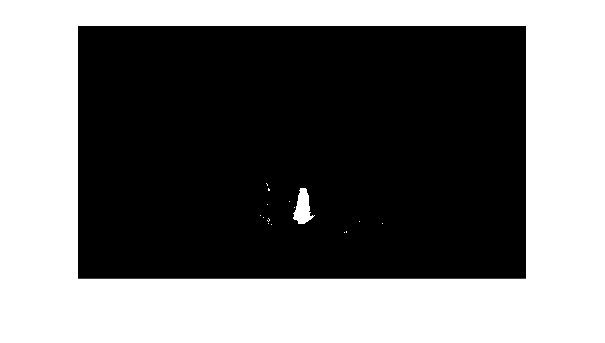

imshow(bw)

for i=121:121
    img = readFrame(grayInput);
    bw = FireEscape(img);
end
grayInput.CurrentTime =0;

imshow(bw)

img1 = imread("FirstFrameRocket.bmp");
img2 = imread("MiddleFrameRocket.bmp");
img3 = imread("rocketLastFrame.bmp");
img1 = im2gray(img1);
img2 = im2gray(img2);
img3 = im2gray(img3);

BW1 = FlameMask(img1);
BW2 = FlameMask(img2);
BW3 = FlameMask(img3);


nnz(BW1)

ans = 520

nnz(BW2)

ans = 3072

nnz(BW3)

ans = 5497


nnz(BW2)/nnz(BW1)

ans = 5.9077